# 案例：Matlab 绘图颜色搭配

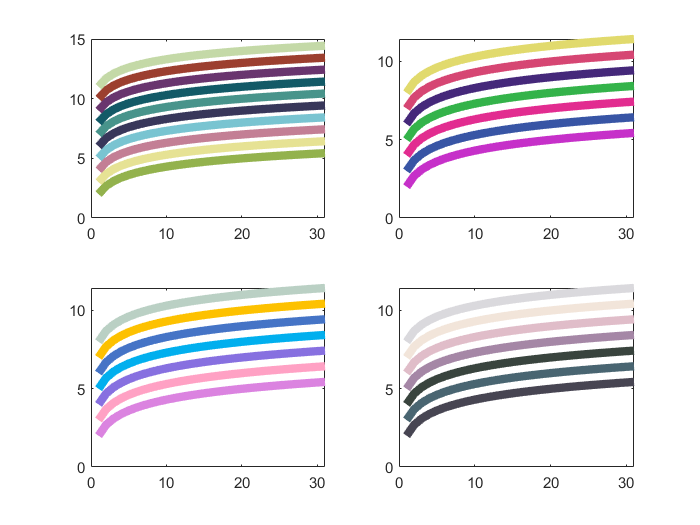

clear;clc;close all;
cString = {'#93B24D', '#E6E294', '#C37F95', '#79C4D1', '#38375A', ...
           '#48948B', '#135A67', '#69356E', '#9C3F2F', '#C4D9A7'};
cString2 = {'#C630C9', '#3855A5', '#E22C90', '#34B34A', '#45287A', '#D64673', '#E1DA6D', ...
            '#DB83E0', '#FFA1C4', '#8770E0', '#01AFEE', '#4574C6', '#FDC100', '#BAD0C4', ...
            '#474552', '#496571', '#39443E', '#A587A6', '#E0BDC9', '#F2E5DA', '#DAD9DD'};
cStrings = [cString, cString2];
count = length(cStrings);
x = 1:count;
y = log(x) + 1;
c = zeros(count, 3);
for i = 1:length(cString2)
    c(i, :) = String2Color(cString2{i});
end
% 每一行就是一种颜色
% c_map2 = c/256;
c_map = [0.57, 0.69, 0.30
         0.89, 0.88, 0.57
         0.76, 0.49, 0.58
         0.47, 0.76, 0.81
         0.21, 0.21, 0.35
         0.28, 0.57, 0.54
         0.07, 0.35, 0.40
         0.41, 0.20, 0.42
         0.60, 0.24, 0.18
         0.76, 0.84, 0.65];
c_map2 = [0.77, 0.18, 0.78
          0.21, 0.33, 0.64
          0.88, 0.17, 0.56
          0.20, 0.69, 0.28
          0.26, 0.15, 0.47
          0.83, 0.27, 0.44
          0.87, 0.85, 0.42
          0.85, 0.51, 0.87
          0.99, 0.62, 0.76
          0.52, 0.43, 0.87
          0.00, 0.68, 0.92
          0.26, 0.45, 0.77
          0.98, 0.75, 0.00    
          0.72, 0.81, 0.76
          0.77, 0.18, 0.78
          0.28, 0.39, 0.44
          0.22, 0.26, 0.24
          0.64, 0.52, 0.64
          0.87, 0.73, 0.78
          0.94, 0.89, 0.85
          0.85, 0.84, 0.86];
figure;
subplot(2, 2, 1);
for m = 1:10
    plot(x, y + m, 'color', cString{m}, 'LineWidth', 5);
    hold on
end
hold off
for m = 1:3
    subplot(2, 2, m + 1);
    for i = 1:7
        plot(x, y + i, 'color', cString2{7*m - 7 + i}, 'LineWidth', 5);
        hold on
    end
    hold off
end

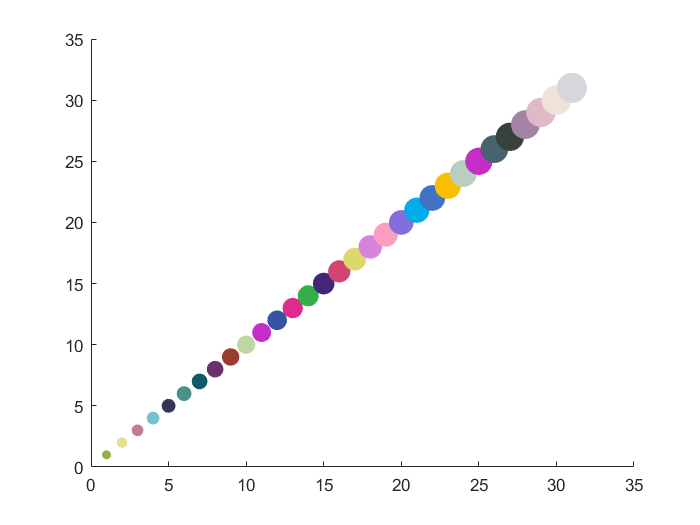

figure;
colormap([c_map; c_map2]);
scatter(x, x, 10*x + 20, x, 'filled');

function c = String2Color(str)
clist = '0123456789ABCDEF';
nums = zeros(1, 6);
for i = 1:6
    nums(i) = find(str(i + 1) == clist);
end
c = zeros(1, 3);
for i = 1:3
    c(i) = 16 * (nums(2*i-1) - 1) + (nums(2*i) - 1);
end
end

